2-

a.

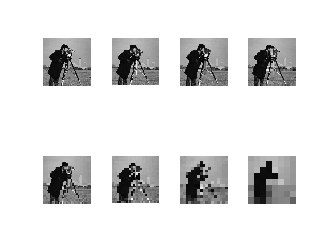

img = imread("cameraman.tif");
subplot(2,4,1)
imshow(img)
r = [64 55 45 36 27 17 8];
for i = 1 : max(size(r))
    subplot(2, 4, i+1)
    resized = imresize(img, r(i)/256,"nearest");
    imshow(resized)
end

clf

b.

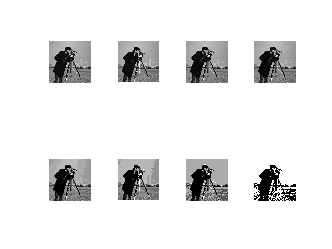

k = 2.^(8:-1:1);
subplot(2,4,1)
imshow(img)
for i = 1 : max(size(k))-1
    subplot(2,4,i+1)
    img_quant = uint8(floor(double(img) / (255/k(i+1))) * (255/k(i+1)));
    scaler = double(max(unique(img_quant)));
    scaler = double(scaler/255);
    img_quant = img_quant./ scaler;
    imshow(img_quant)
end

clf

3

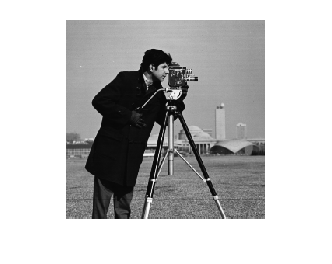

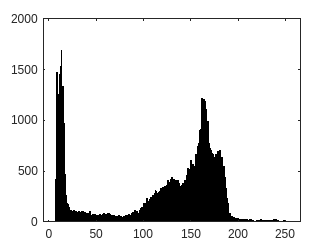

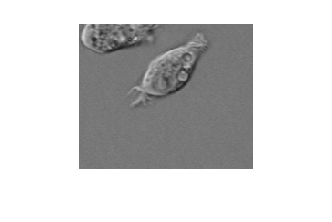

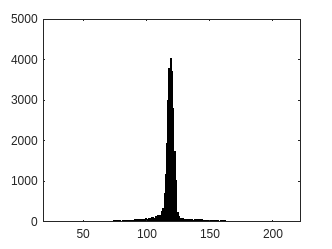

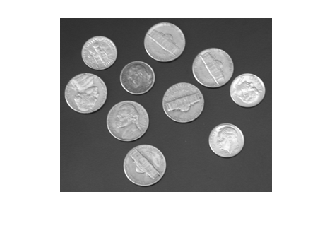

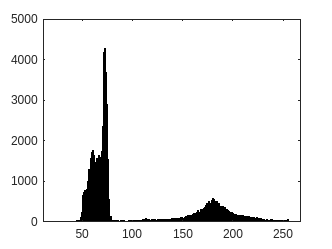

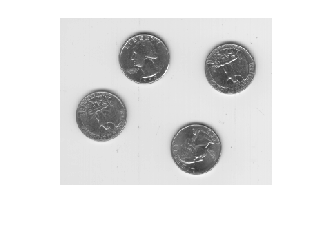

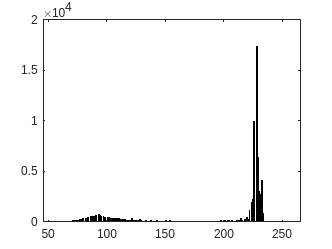

sisalto = dir("grayscaleset");

for n = 1 : 8
    pic = sisalto(n+2).name;
    picture = append("grayscaleset/", pic);
    picture = imread(picture);
    figure;
    imshow(picture);
    figure;
    X = picture';
    X = X(:)';
    histogram(X,256)
end

clf

4

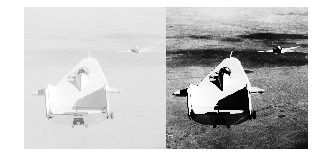

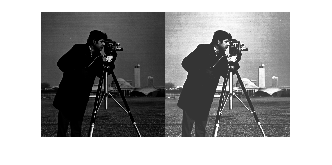

sisalto = dir("kuvat2");
for n = 1 : 2
    pic = sisalto(n+2).name;
    picture = append("kuvat2/", pic);
    picture = imread(picture);

    new_pic = histeq(picture,256);
    picture = horzcat(picture,new_pic);
    figure;
    imshow(picture);

end

5.

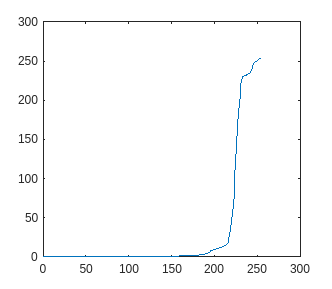

pic = imread("kuvat2/kuvahigh1.png");
P_r = histcounts(pic,256,"Normalization","cdf");
T = 255 * P_r;
plot(0:255,T)

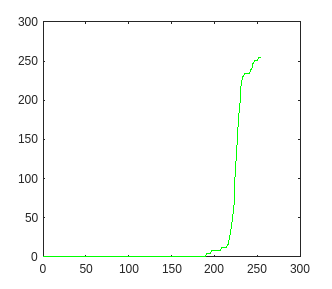

% Vektori sisältää 256 alkiota, koska kuva on 8-bittinen, eli se saa 256
% eri harmaasävyarvoa
[pic, T] = histeq(pic);
T = T*255;
plot(0:255,T,"green")

6

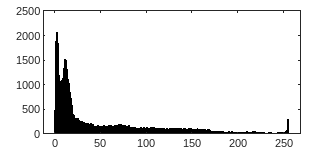

tire = imread("tire.tif");
X = tire';
X = X(:)';

histogram(X,256)

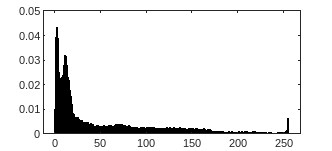

histogram(X,256,"Normalization","probability")

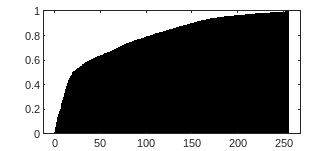

% kuvaa jokaisen arvon todennäköisyyttä esiintyä kuvassa.
histogram(X,256,"Normalization","cdf")

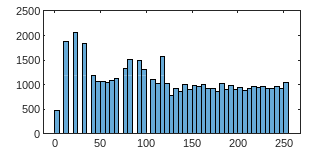

% kuvaa keertymäfunktiota, eli todennäköisyyttä, että 
% kuvassas oleva arvo on pienempi tai yhtä suuri
T = histcounts(X,256,"Normalization","cdf");
tire = tire + 1;
new_pic = zeros(205, 232);
for i = 1 : 205
    for j= 1 : 232
        X = tire(i, j);
        new_pic(i, j) = T(X);
    end
end
new_pic = new_pic * 255;
new_pic = uint8(new_pic);
histogram(new_pic)

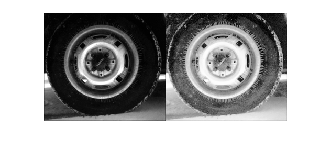

pic2 = horzcat(tire,new_pic);
imshow(pic2)